0 虚拟水体空间

1 幼体七鳃鳗

2 成年雄性七鳃鳗

3 成年雌性七鳃鳗

4 被寄生雄性七鳃鳗

5 被寄生雌性七鳃鳗

6 被寄生幼体

每个元胞每次迭代：

死亡：元胞变为虚拟水体空间

幼体死亡概率  0.05

被寄生幼体死亡概率 0.1

成年雄性死亡概率 0.01

被寄生雄性死亡概率 0.02

成年雌性死亡概率 0.03

被寄生雌性死亡概率 0.06

出生：虚拟水体空间变为幼体

虚拟水体空间 邻居既有雄性又有雌性时 0.5的概率产生幼体

寄生：当周围8个邻居有被寄生个体时

1 幼体七鳃鳗 -> 6 被寄生幼体

2 成年雄性七鳃鳗->4 被寄生雄性七鳃鳗

3 成年雌性七鳃鳗->5 被寄生雌性七鳃鳗

clc
clear
n=200;
p=0.4;
z=zeros(n);
Se=rand(n)<p;
Sd=zeros(n+2);  %矩阵初始化
Ph=image(cat(3,Se,z,z));%初始可视化
while(1)
    Sd(2:n+1,2:n+1)=Se;
    % 周围八个邻居和
    Sum=Sd(1:n,2:n+1)+Sd(3:n+2,2:n+1)+Sd(2:n+1,1:n)+Sd(2:n+1,3:n+2)+Sd(1:n,1:n)+Sd(3:n+2,3:n+2)+Sd(1:n,3:n+2)+Sd(3:n+2,1:n);
    for i=1:n
        for j=1:n
            if Sum(i,j)==3||(Sum(i,j)==2&&Se(i,j)==1)
                Se(i,j)=1;
            else
                Se(i,j)=0;
            end
        end
    end
    
    set(Ph,'cdata',cat(3,Se,z,z))
    % pause(0.03)
    drawnow
end

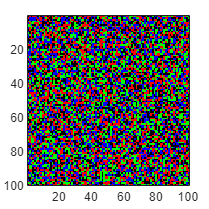

clc
clear

% 初始化参数
n = 100;  % 网格大小
p = 0.4;  % 初始七鳃鳗的概率
z = zeros(n);  % 辅助零矩阵
S = randi([0, 3], n);  % 随机初始化状态 (0到3之间的整数)
Sd = zeros(n+2);  % 扩展矩阵用于计算邻居
Ph = image(cat(3, (S==1), (S==2), (S==3)));  % 初始可视化

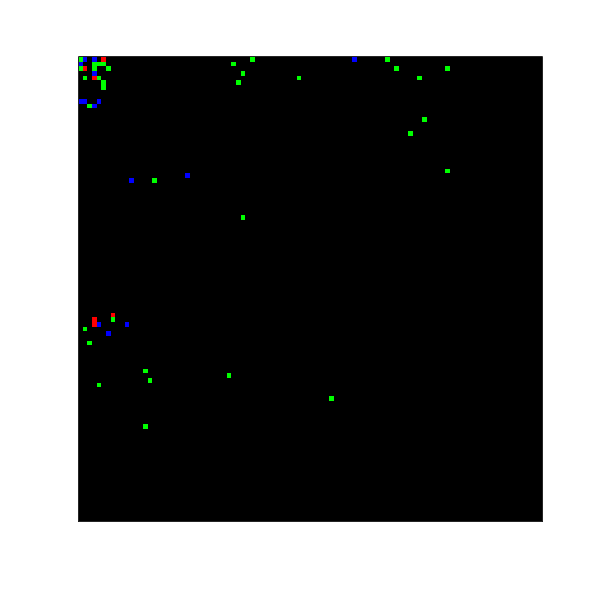


% 初始可视化
figure;
Ph = imagesc(S);  % 使用 imagesc 以便更好的颜色映射
colormap([1 1 1; 0 1 0; 0 0 1; 1 0 0; 1 0.5 0; 1 0 1; 0.5 0.5 0.5]); % 定义颜色映射
axis equal tight;  % 设置坐标轴为等比例和紧凑
set(gca, 'XLim', [0.5, n+0.5], 'YLim', [0.5, n+0.5]);  % 设置坐标轴限制
set(gca, 'XTick', [], 'YTick', []);  % 移除坐标轴的刻度

% 调整图形窗口尺寸
set(gcf, 'Position', [100, 100, 600, 600]);  % 设置图形窗口位置和尺寸

% 定义死亡概率
deathRates = [0, 0.05, 0.01, 0.03, 0.02, 0.06, 0.1];  % 从0到6的死亡概率

% 迭代过程
while true
    % 更新状态
    Sd(2:n+1, 2:n+1) = S;

    % 随机移动逻辑
    for i = 1:n
        for j = 1:n
            if S(i, j) ~= 0  % 如果当前位置有七鳃鳗
                % 获取周围空白位置
                emptyNeighbors = find(Sd(i:i+2, j:j+2) == 0);
    
                % 排除中心点（即原位置）
                emptyNeighbors = emptyNeighbors(emptyNeighbors ~= 5);
    
                if ~isempty(emptyNeighbors)
                    % 随机选择一个空白位置进行移动
                    moveIdx = emptyNeighbors(randi(length(emptyNeighbors)));
                    [moveI, moveJ] = ind2sub([3, 3], moveIdx);
                    
                    % 确保新位置在Sd的有效范围内
                    newI = i + moveI - 2;
                    newJ = j + moveJ - 2;
                    if newI >= 1 && newI <= n && newJ >= 1 && newJ <= n
                        Sd(newI+1, newJ+1) = S(i, j);  % 移动到新位置
                        Sd(i+1, j+1) = 0;  % 将原位置设为0
                    end
                end
            end
        end
    end
    S = Sd(2:n+1, 2:n+1);  % 更新状态
    
    % 计算邻居状态
    neighbors = Sd(1:n,2:n+1)+Sd(3:n+2,2:n+1)+Sd(2:n+1,1:n)+Sd(2:n+1,3:n+2)+Sd(1:n,1:n)+Sd(3:n+2,3:n+2)+Sd(1:n,3:n+2)+Sd(3:n+2,1:n);
    
    % 创建一个新的状态矩阵
    newS = S;
    
    for i = 1:n
        for j = 1:n
            % 死亡判断
            if rand() < deathRates(S(i,j) + 1)
                newS(i,j) = 0;  % 元胞变为虚拟水体空间
            end
            
            % 出生判断
            if S(i,j) == 0 && any(neighbors(i,j) == 2) && any(neighbors(i,j) == 3) && rand() < 0.5
                newS(i,j) = 1;  % 生成幼体
            end

            % 寄生判断
            if any(neighbors(i,j) == 4 | neighbors(i,j) == 5 | neighbors(i,j) == 6)
                if S(i,j) == 1
                    newS(i,j) = 6;  % 幼体七鳃鳗变为被寄生幼体
                elseif S(i,j) == 2
                    newS(i,j) = 4;  % 成年雄性变为被寄生雄性
                elseif S(i,j) == 3
                    newS(i,j) = 5;  % 成年雌性变为被寄生雌性
                end
            end
        end
    end
    
    % 更新状态
    S = newS;
    
    % 更新可视化
    set(Ph, 'CData', cat(3, (S==1), (S==2), (S==3)))
    drawnow
    
    % 暂停（可选）
    % pause(0.03)
end

clc
clear

% 初始化参数
n = 200;  % 网格大小
S = randi([0, 3], n);  % 随机初始化状态 (0到3之间的整数)
Sd = zeros(n+2);  % 扩展矩阵用于计算邻居

% 初始可视化
figure;
Ph = imagesc(S);  % 使用 imagesc 以便更好的颜色映射
colormap([1 1 1; 0 1 0; 0 0 1; 1 0 0; 1 0.5 0; 1 0 1; 0.5 0.5 0.5]); % 定义颜色映射
axis equal tight;

% 定义死亡概率
deathRates = [0, 0.05, 0.01, 0.03, 0.02, 0.06, 0.1];  % 从0到6的死亡概率

% 初始设置一小块区域包含被寄生个体
initParasiteArea = [50, 50, 10, 10]; % x, y, width, height
S(initParasiteArea(2):(initParasiteArea(2)+initParasiteArea(4)), initParasiteArea(1):(initParasiteArea(1)+initParasiteArea(3))) = 4;

% 迭代过程
while true
    % 更新状态
    Sd(2:n+1, 2:n+1) = S;
    
    % 随机移动逻辑
    for i = 1:n
        for j = 1:n
            if S(i, j) ~= 0  % 如果当前位置有七鳃鳗
                % 获取周围空白位置
                emptyNeighbors = find(Sd(i:i+2, j:j+2) == 0);
    
                % 排除中心点（即原位置）
                emptyNeighbors = emptyNeighbors(emptyNeighbors ~= 5);
    
                if ~isempty(emptyNeighbors)
                    % 随机选择一个空白位置进行移动
                    moveIdx = emptyNeighbors(randi(length(emptyNeighbors)));
                    [moveI, moveJ] = ind2sub([3, 3], moveIdx);
                    
                    % 确保新位置在Sd的有效范围内
                    newI = i + moveI - 2;
                    newJ = j + moveJ - 2;
                    if newI >= 1 && newI <= n && newJ >= 1 && newJ <= n
                        Sd(newI+1, newJ+1) = S(i, j);  % 移动到新位置
                        Sd(i+1, j+1) = 0;  % 将原位置设为0
                    end
                end
            end
        end
    end
    S = Sd(2:n+1, 2:n+1);  % 更新状态

    % 计算邻居状态
    neighbors = Sd(1:n,2:n+1)+Sd(3:n+2,2:n+1)+Sd(2:n+1,1:n)+Sd(2:n+1,3:n+2)+Sd(1:n,1:n)+Sd(3:n+2,3:n+2)+Sd(1:n,3:n+2)+Sd(3:n+2,1:n);
    
    % 创建一个新的状态矩阵
    newS = S;
    
    for i = 1:n
        for j = 1:n
            % 死亡判断
            if rand() < deathRates(S(i,j) + 1)
                newS(i,j) = 0;  % 元胞变为虚拟水体空间
            end
            
            % 出生判断
            if S(i,j) == 0 && any(neighbors(i,j) == 2) && any(neighbors(i,j) == 3) && rand() < 0.5
                newS(i,j) = 1;  % 生成幼体
            end

            % 寄生逻辑
            if any(neighbors(i,j) == 4 | neighbors(i,j) == 5 | neighbors(i,j) == 6)
                if rand() < 0.3  % 增加寄生传播的概率
                    if S(i,j) == 1
                        newS(i,j) = 6;  % 幼体七鳃鳗变为被寄生幼体
                    elseif S(i,j) == 2
                        newS(i,j) = 4;  % 成年雄性变为被寄生雄性
                    elseif S(i,j) == 3
                        newS(i,j) = 5;  % 成年雌性变为被寄生雌性
                    end
                end
            end
        end
    end
    
    % 更新状态
    S = newS;
    
    % 更新可视化
    set(Ph, 'CData', S);
    drawnow
    
    % 暂停（可选）
    pause(0.03)
end
